clearvars;

samples = 500

samples = 500

Ustawienia

Filename = "sin.wav";
Bit_resolution = 4;
Dither_level = 0.2;
PDF = "triangular";
Noise_shaping = true;


Wczytanie pliku i wygenerowanie szumu

[x, Fs] = audioread(Filename);

wav_size = size(x);
length = wav_size(1);

if wav_size(2) > 1
    x = x(:, 1);
end

white_noise = wgn(length, 1, 0);
pink_noise = pinknoise(length);
blue_noise = bluenoise(length, 1);

dither = createDither(Bit_resolution, length, PDF, Noise_shaping);

Normalizacja szumów

white_noise = white_noise*max(x)/max(white_noise);
pink_noise = pink_noise*max(x)/max(pink_noise);
blue_noise = blue_noise*max(x)/max(blue_noise);

Zsumowanie szumów z nagraniem

x_2 = x + white_noise;
x_3 = x + pink_noise;
x_4 = x + blue_noise;
x_dither = x + dither;

Zmiana poziomu kwantyzacji

x_quant = quant(x, Bit_resolution, true, 0, 0);
x_quant_2 = quant(x_2, Bit_resolution, true, 0, 0);
x_quant_3 = quant(x_3, Bit_resolution, true, 0, 0);
x_quant_4 = quant(x_4, Bit_resolution, true, 0, 0);
x_quant_dither = quant(x_dither, Bit_resolution, true, 0, 0);

Wyznaczenie szumu kwantyzacji dla nagrania oryginalnego

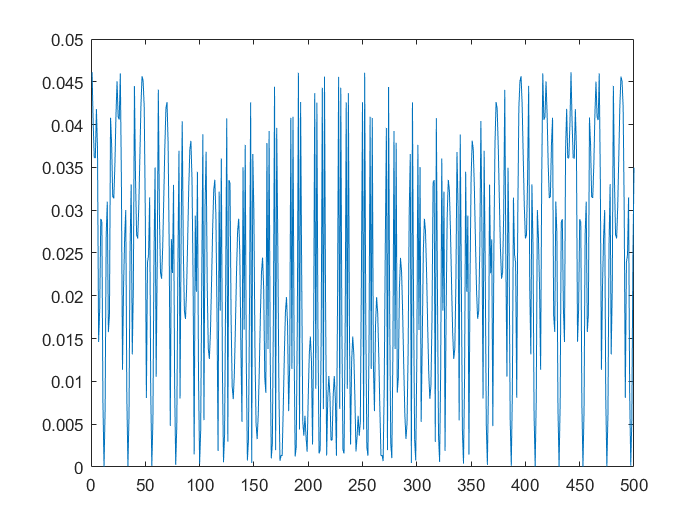

x_diff = abs(x - x_quant');
plot(1:samples, x_diff(1:samples))


"Suma szumu kwantyzacji"

ans = "Suma szumu kwantyzacji"

sum(x_diff)

ans = 4.7149e+03


x_diff_2 = abs(x - x_quant_dither');
plot(1:samples, x_diff(1:samples))


"Suma szumu kwantyzacji po ditheringu"

ans = "Suma szumu kwantyzacji po ditheringu"

sum(x_diff_2)

ans = 8.2327e+03

Wyznaczenie FFT


"Przed kwantyzacją, bez szumu"

ans = "Przed kwantyzacją, bez szumu"

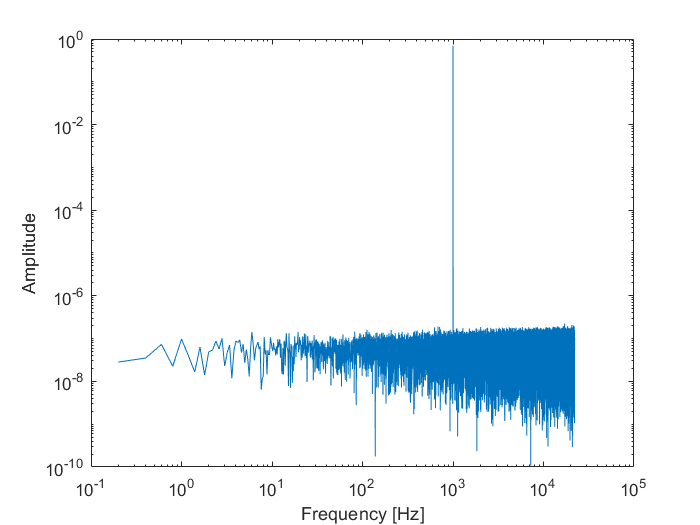

figure(1)
[y, P] = fft_plot(x, length, Fs);


"Przed kwantyzacją, z szumem białym"

ans = "Przed kwantyzacją, z szumem białym"

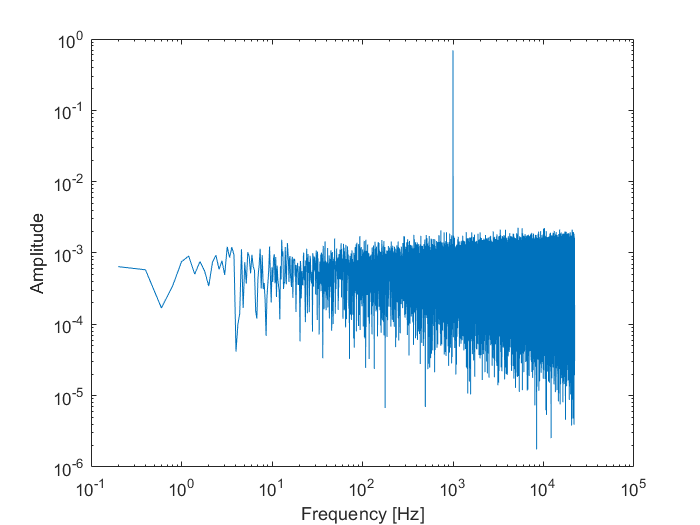

figure(2)
[y_2, P_2] = fft_plot(x_2, length, Fs);


"Bez szumu"

ans = "Bez szumu"

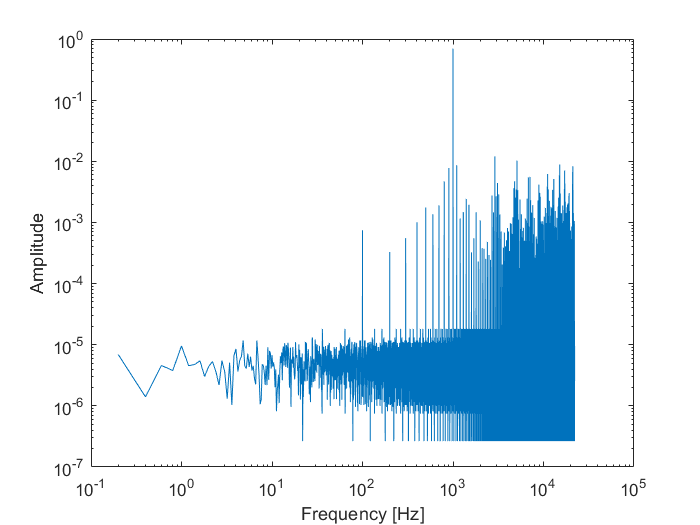

figure(3)
[y_quant, P_quant] = fft_plot(x_quant, length, Fs);

"Szum biały"

ans = "Szum biały"

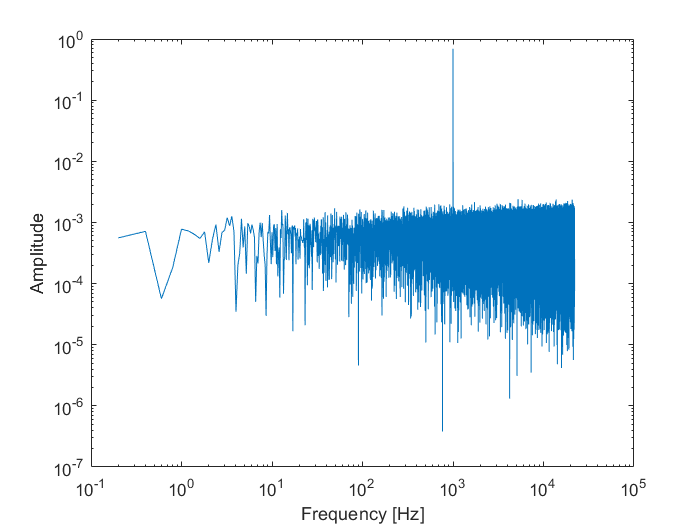

figure(4)
[y_quant_2, P_quant_2] = fft_plot(x_quant_2, length, Fs);

"Szum różowy"

ans = "Szum różowy"

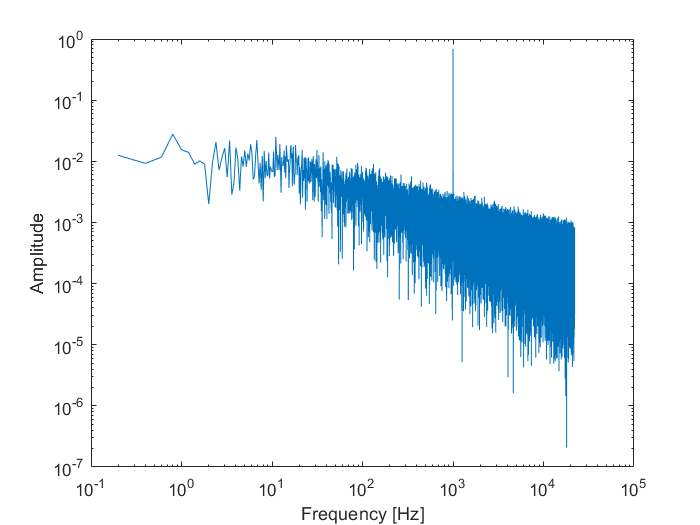

figure(5)
[y_quant_3, P_quant_3] = fft_plot(x_quant_3, length, Fs);

"Szum niebieski"

ans = "Szum niebieski"

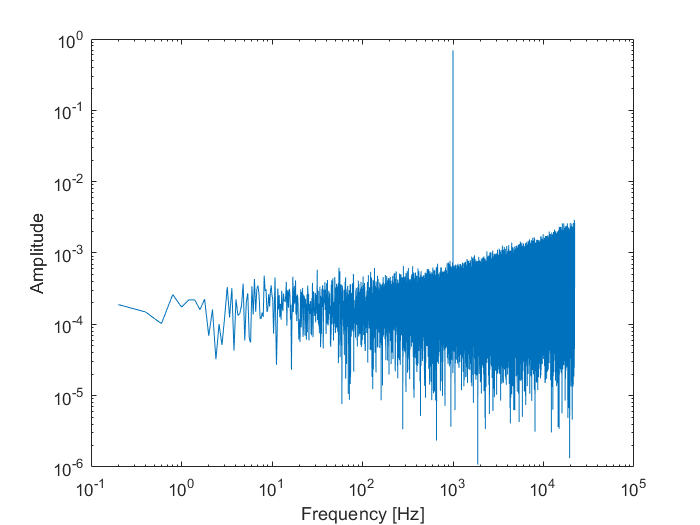

figure(6)
[y_quant_4, P_quant_4] = fft_plot(x_quant_4, length, Fs);

"Dither"

ans = "Dither"

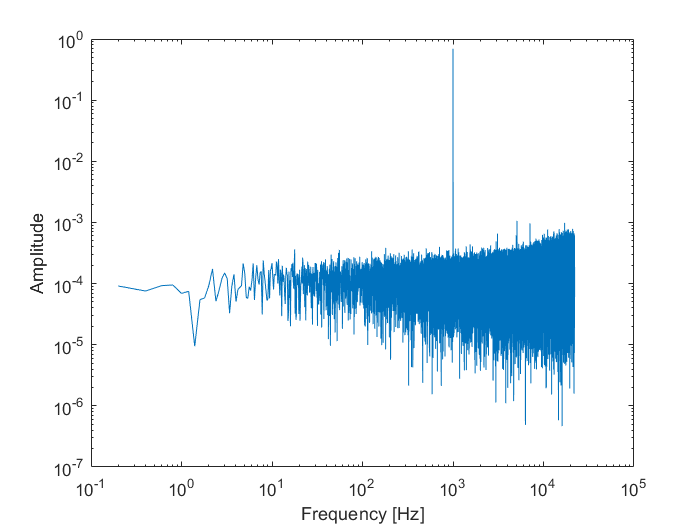

figure(7)
[y_quant_5, P_quant_5] = fft_plot(x_quant_dither, length, Fs);



"Bez szumu"

ans = "Bez szumu"

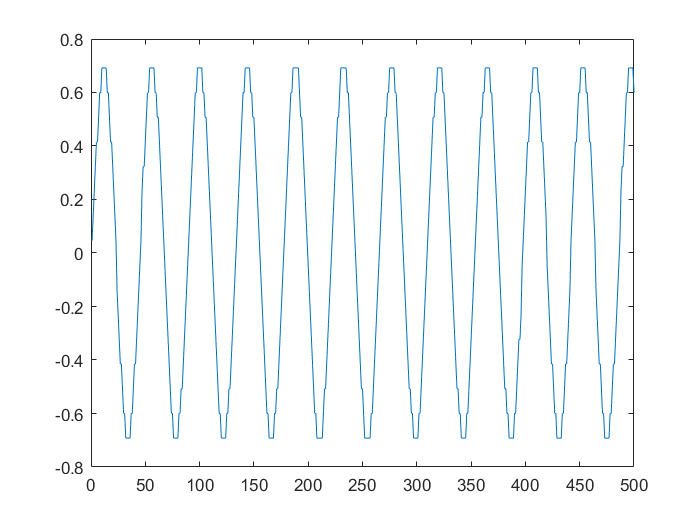

plot(1:samples, x_quant(1:samples))

"Szum biały"

ans = "Szum biały"

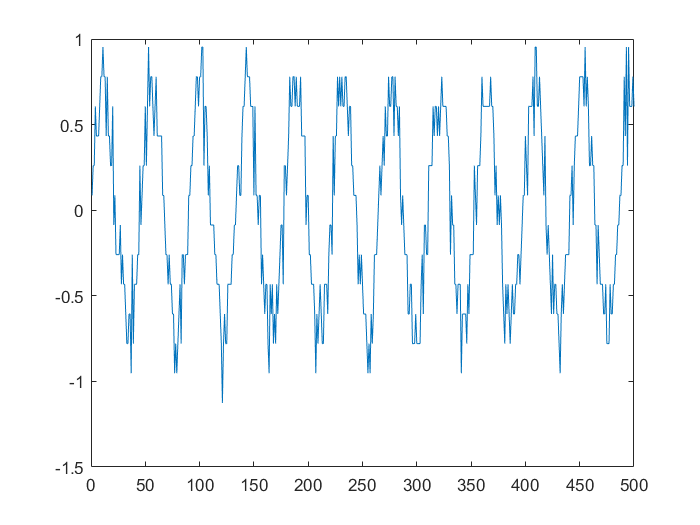

plot(1:samples, x_quant_2(1:samples))

"Szum różowy"

ans = "Szum różowy"

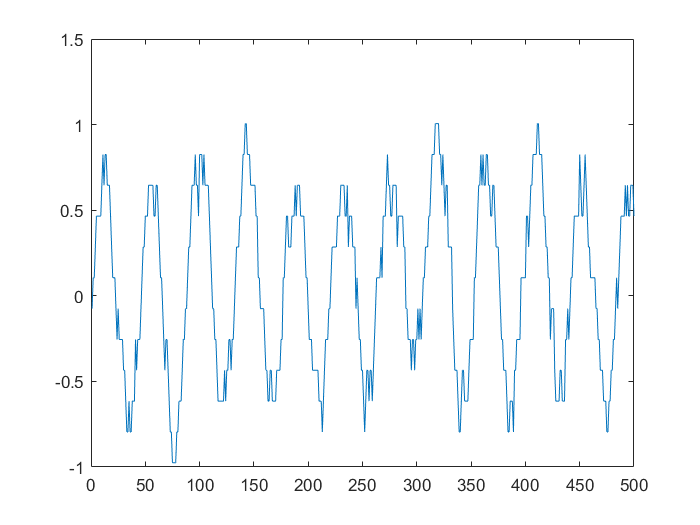

plot(1:samples, x_quant_3(1:samples))

"Szum niebieski"

ans = "Szum niebieski"

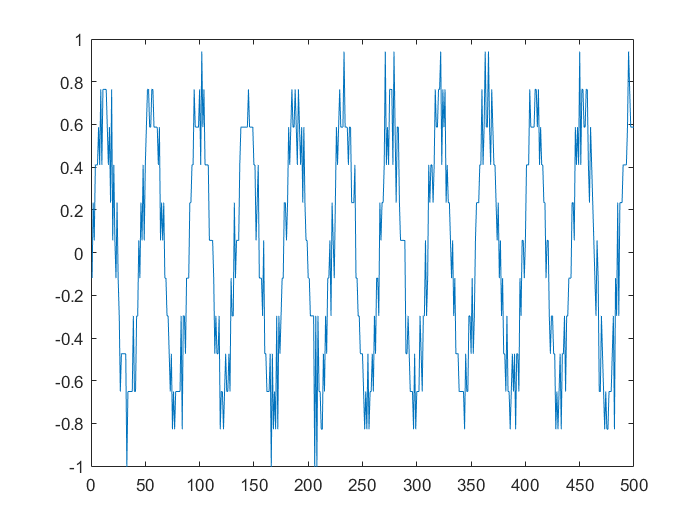

plot(1:samples, x_quant_4(1:samples))

"Dither"

ans = "Dither"

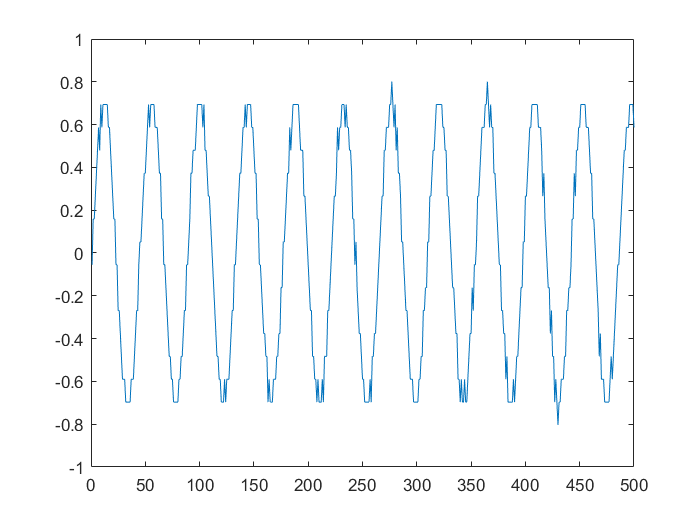

plot(1:samples, x_quant_dither(1:samples))